# Problem 3

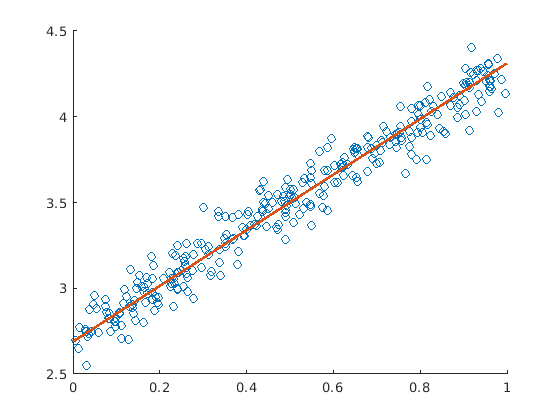

data = load('../data/points2D_Set1.mat');
x = getfield(data,"x");
y = getfield(data, "y");
scatter(x,y)

image = [x y].';
image = reshape(image,2,[]);

pca_image = pca_inverse_transform1(image,1);
% saveas(gcf,sprintf('scatter_plt1.png'));

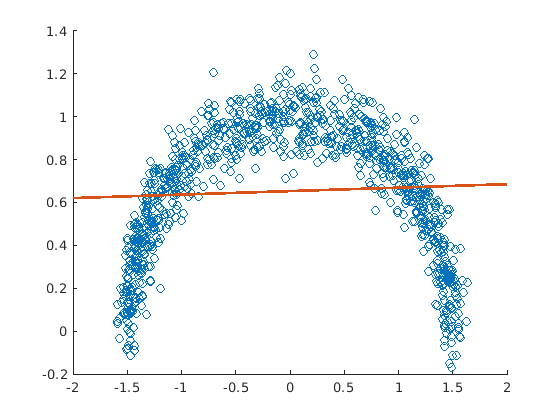


data = load('../data/points2D_Set2.mat');
x = getfield(data,"x");
y = getfield(data, "y");
scatter(x,y)

image = [x y].';
image = reshape(image,2,[]);

pca_image = pca_inverse_transform2(image,1);
% saveas(gcf,sprintf('scatter_plt2.png'));

function y = pca_inverse_transform1(imgvec,n)
    dim = size(imgvec);
    freq = dim(2);
    
    mean = sum(imgvec,2)/freq;
    imgvec_centered = imgvec - mean;
  
    %for j = 1:freq
    %   covariance = covariance + imgvec_centered(:,j)*imgvec_centered(:,j).';
    %end
    %covariance = covariance/freq - mean*mean.'
    covariance=imgvec_centered*imgvec_centered'./freq;
    
    [Q,D] = eig(covariance);
    [~,ind] = sort(diag(D),'descend');
    ind = ind(1:n);
    U = Q(:,ind);
    slope = U(2)/U(1);
    x=0:1;
    y=slope*(x-mean(1))+mean(2);
    hold on
    plot(x,y,"LineWidth",2)
    hold off
    Y = U.'*squeeze(imgvec);
    y = reshape(U*Y,dim(1),freq);
end

function y = pca_inverse_transform2(imgvec,n)
    dim = size(imgvec);
    freq = dim(2);
    
    mean = sum(imgvec,2)/freq;
    imgvec_centered = imgvec - mean;
  
    %for j = 1:freq
    %   covariance = covariance + imgvec_centered(:,j)*imgvec_centered(:,j).';
    %end
    %covariance = covariance/freq - mean*mean.'
    covariance=imgvec_centered*imgvec_centered'./freq;
    
    [Q,D] = eig(covariance);
    [~,ind] = sort(diag(D),'descend');
    ind = ind(1:n);
    U = Q(:,ind);
    slope = U(2)/U(1);
    x=-2:2;
    y=slope*(x-mean(1))+mean(2);
    hold on
    plot(x,y,'LineWidth',2)
    hold off
    Y = U.'*squeeze(imgvec);
    y = reshape(U*Y,dim(1),freq);
end
